# Battery Degradation Models

load batteryParams.mat;
load ukfBatteryParams.mat;
global batteryParams;

## R0

- degrade from .0011368 to .212 exponentially

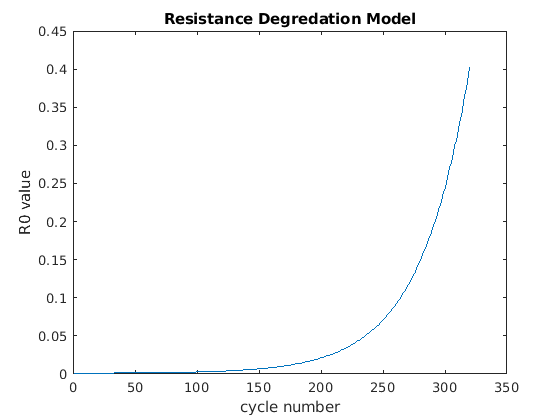

R0d    = zeros(320,1);
R0d(1) = 0.001136807670048;

for i = 2:320
    R0d(i) = degradeR0(R0d(i-1), i);
end
f1 = figure(1); clf;
plot(R0d);
title("Resistance Degredation Model");
ylabel("R0 value");
xlabel("cycle number");

disp(R0d(1));

    0.0011



disp(R0d(320));

    0.4034



## Q

- degrade from 3.8 to 2.6 semi-exponentially

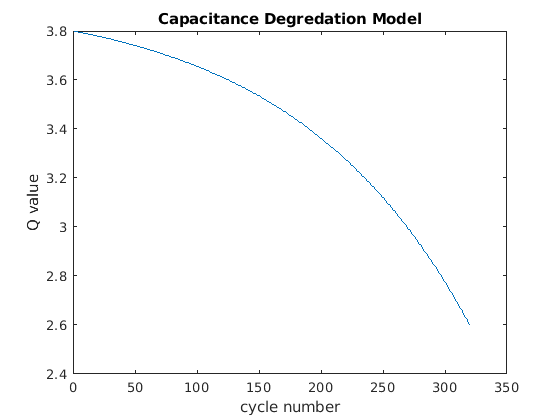

Qd    = zeros(320,1);
Qd(1) = 3.8;

for i = 2:320
    Qd(i) = degradeQ(Qd(i-1), i);
end
f2 = figure(2); clf;
plot(Qd);
title("Capacitance Degredation Model");
ylabel("Q value");
xlabel("cycle number");

disp(Qd(1));

    3.8000



disp(Qd(320));

    2.5978



# Degradation Experiment

- sim 320 times

- degrade R0 and Q each time

- store params in arrays

- store SOC and voltage curves in cell array

load batteryParams.mat;

k       = 320; % number of cycles
v{k,1}  = []; % preallocate space
z{k,1}  = [];
%R0a     = zeros(k,1);
Qa      = zeros(k+1,1);
%R0_orig = batteryParams.R0; % 0.001136807670048
Q_orig  = batteryParams.Q; % 3.8
%R0a(1)  = batteryParams.R0; % initialize param vals
Qa(1)   = batteryParams.Q;
i_count = zeros(k,1);
tic
for i = 2:k+1
    simout = sim('batteryMine');
    v{i-1} = simout.voltage.Data;
    z{i-1} = simout.soc.Data;
    % mle of Q, fit Q to degradation
    
    %batteryParams.R0 = batteryParams.R0_degradation((i-1)*40);
    batteryParams.Q  = batteryParams.Q_degradation((i-1));
    
%    R0a(i) = batteryParams.R0;
    Qa(i)  = batteryParams.Q;
   
    save('batteryParams.mat', 'batteryParams');
%     
%     if mod((i-1),8)
         save('voltage_profiles.mat', 'v');
         save('soc_profiles.mat', 'z');
 %        save('R0_labels.mat', 'R0a');
         save('Q_labels.mat', 'Qa');
         save('i_count.mat', 'i_count');
%     end
end
toc

Elapsed time is 9960.544665 seconds.


%batteryParams.R0 = R0_orig;
batteryParams.Q  = Q_orig;
save('batteryParams.mat', 'batteryParams');

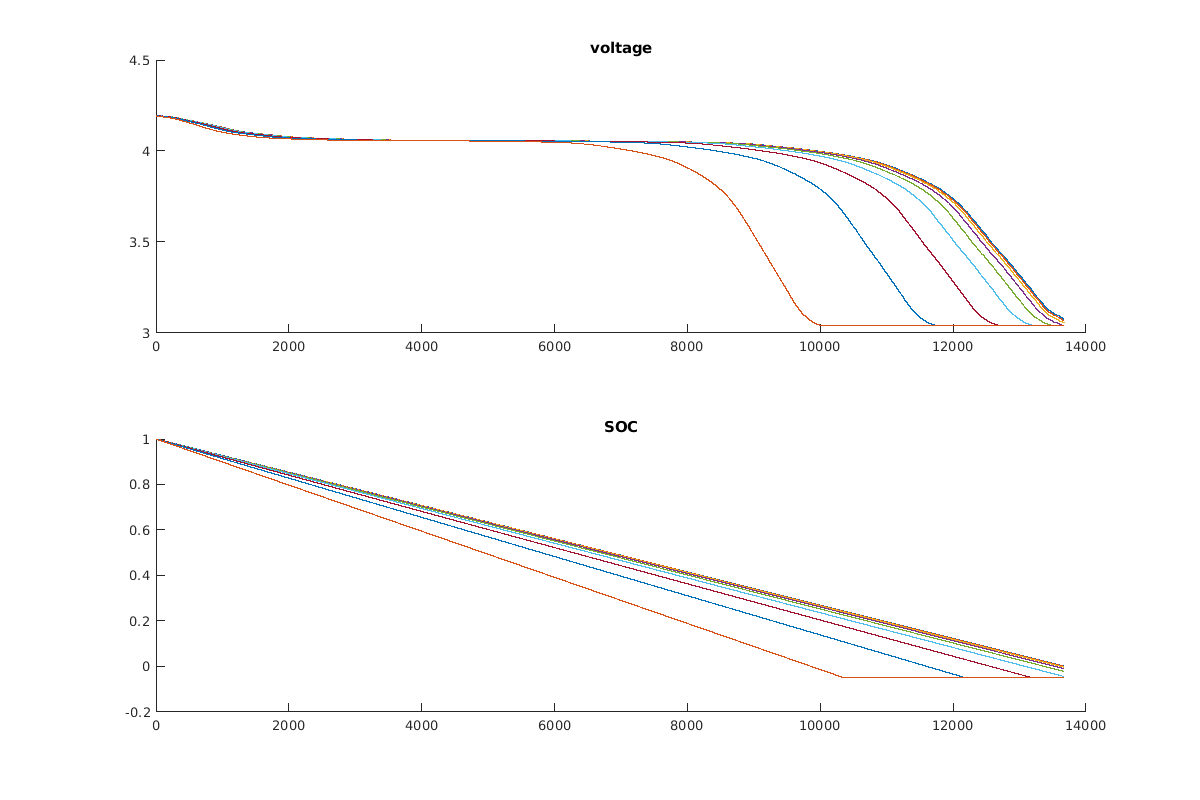

f3  = figure(3); clf;
f3.Position = [0 0 1200 800];
subplot(211);
hold on;
plot(smoothdata(v{1}, 'movmean', 500));
for i = 1:8
    plot(smoothdata(v{i*40}, 'movmean', 500));
end
hold off;
title("voltage");
ylim([3 4.5])

subplot(212);
hold on;
plot(z{1});
for i = 1:8
    plot(z{i*40});
end
hold off;
title("SOC");

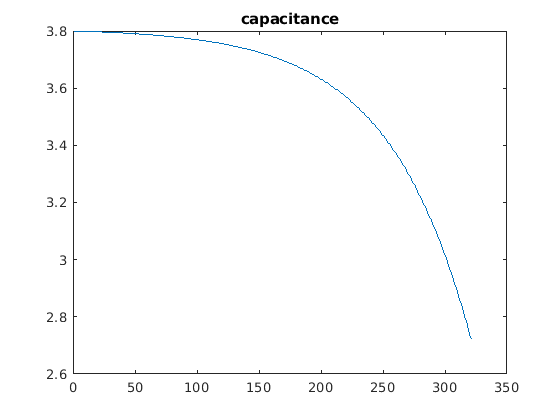


f4 = figure(4); clf;
plot(Qa);
title("capacitance");

## R0 Degradation

function R0 = degradeR0(R0, cycle)
    R0 = R0 + (exp(.025*cycle) / (300000));
end


## Q Degradation

function Q = degradeQ(Q, cycle)
     Q = Q - (exp(.007*cycle) / (1000));
end


